# Actividad 7: Evaluación final

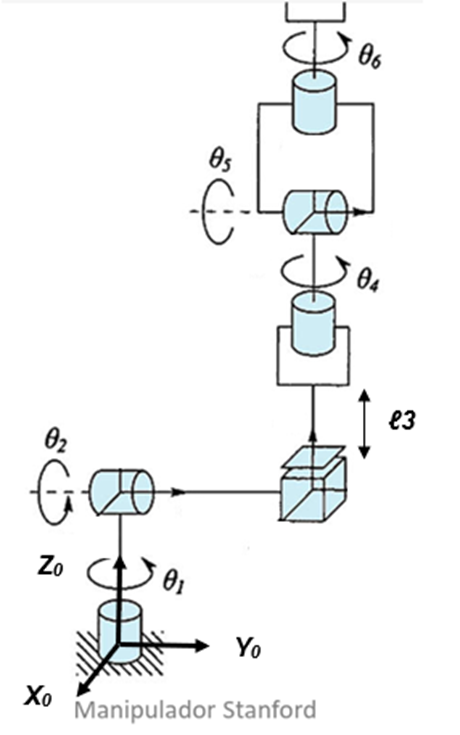

## Inicialización y Declaración de Variables

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

tic
%Declaración de variables simbólicas
syms th1(t) th2(t) l3(t) th4(t) th5(t) th6(t) t l1 l2 l4 l5 l6
syms th1p(t) th2p(t) l3p(t) th4p(t) th5p(t) th6p(t)
syms th1pp(t) th2pp(t) l3pp(t) th4pp(t) th5pp(t) th6pp(t)
syms m1 m2 m3 m4 m5 m6 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 Ixx4 Iyy4 Izz4 Ixx5 Iyy5 Izz5 Ixx6 Iyy6 Izz6  %Masas y matrices de Inercia
syms lc1 lc2 lc3 lc4 lc5 lc6 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

Se configura el robot con seis articulaciones rotacionales, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0 0 1 0 0 0];

Creamos el vector de coordenadas generalizadas

Q= [th1; th2; l3; th4; th5; th6];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
/ th1(t) \
|        |
| th2(t) |
|        |
|  l3(t) |
|        |
| th4(t) |
|        |
| th5(t) |
|        |
\ th6(t) /



Creamos el vector de velocidades generalizadas.

Qp= [th1p; th2p; l3p; th4p; th5p; th6p];
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/ th1p(t) \
|         |
| th2p(t) |
|         |
|  l3p(t) |
|         |
| th4p(t) |
|         |
| th5p(t) |
|         |
\ th6p(t) /



Creamos el vector de aceleraciones articulares. La aceleración articular es la derivada temporal de las velocidades articulares.

Qpp= [th1pp; th2pp; l3pp; th4pp; th5pp; th6pp];
disp('Aceleraciones generalizadas'); pretty (Qpp);

Aceleraciones generalizadas
/ th1pp(t) \
|          |
| th2pp(t) |
|          |
|  l3pp(t) |
|          |
| th4pp(t) |
|          |
| th5pp(t) |
|          |
\ th6pp(t) /



Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot, en este caso 6 GDL.

GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

### Articulación 1

Se presenta una rotación positiva de 90 en y


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_y \left(90\right)\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \sin \left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$$


Y una rotación positiva de 90 en x


$$\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \sin \left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack \times R_x \left(90\right)\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & \cos \left(\theta \right) & \sin \left(\theta \right)\\
0 & \sin \left(\theta \right) & -\cos \left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$$


%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0; 0; l1];

%Matriz de rotación de la junta 1 a 2
R(:,:,1)= [0  cos(th1)   sin(th1) ;
           0  sin(th1)  -cos(th1) ;
          -1  0          0];

### Articulación 2

Se presenta una rotación negativa de 90 en y


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_y \left(-90\right)\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & -\cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & -\sin \left(\theta \right)\\
1 & 0 & 0
\end{array}\right\rbrack$$


%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [l2*cos(th2); l2*sin(th2); 0];

%Matriz de rotación de la junta 2 a 3
R(:,:,2)= [0  -sin(th2)  -cos(th2) ;
           0   cos(th2)  -sin(th2) ;
           1   0          0];

### Articulación 3 

Para este caso utilizamos la matriz identidad, esto debido a que no hay transformación adicional entre estos sistemas de referencia, lo que significa que los ejes quedan alineados sin modificaciones en posición u orientación.


$$I=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0; l3];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)=   [1  0  0;
             0  1  0;
             0  0  1];

### Articulación 4

Se presenta una rotación positiva de 90 en y


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_y \left(90\right)\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
-1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & \cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & \sin \left(\theta \right)\\
-1 & 0 & 0
\end{array}\right\rbrack$$


%Posición de la articulación 4 respecto a 3
P(:,:,4)= [0; 0; l4];

%Matriz de rotación de la junta 4 respecto a 3
R(:,:,4)=   [0 -sin(th4)  cos(th4);
             0  cos(th4)  sin(th4);
            -1  0         0];

### Articulación 5

Se presenta una rotación negativa de 90 en y


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\mathrm{sen}\theta  & 0\\
\mathrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \times R_y \left(-90\right)\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\sin \left(\theta \right) & -\cos \left(\theta \right)\\
0 & \cos \left(\theta \right) & -\sin \left(\theta \right)\\
1 & 0 & 0
\end{array}\right\rbrack$$


%Posición de la articulación 5 respecto a 4
P(:,:,5)= [l5*cos(th5); l5*sin(th5); 0];

%Matriz de rotación de la junta 5 respecto a 4
R(:,:,5)=   [0 -sin(th5) -cos(th5);
             0  cos(th5) -sin(th5);
             1  0         0];

### Articulación 6

Ya noy hay cambios en los ejes


$$R_z \left(\theta \right)\left\lbrack \begin{array}{ccc}
\cos \theta  & -\textrm{sen}\theta  & 0\\
\textrm{sen}\theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


%Posición de la articulación 6
P(:,:,6)= [0; 0; l6];

%Matriz de rotación de la junta 6
R(:,:,6)=   [cos(th6) -sin(th6)  0;
             sin(th6)  cos(th6)  0;
               0         0       1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty(A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/  0, cos(th1(t)),  sin(th1(t)),  0 \
|                                   |
|  0, sin(th1(t)), -cos(th1(t)),  0 |
|                                   |
| -1,      0,            0,      l1 |
|                                   |
\  0,      0,            0,       1 /



Matriz de Transformación global T1
/  0, cos(th1(t)),  sin(th1(t)),  0 \
|                                   |
|  0, sin(th1(t)), -cos(th1(t)),  0 |
|                                   |
| -1,      0,            0,      l1 |
|                                   |
\  0,      0,            0,       1 /



Matriz de Transformación local A2
/ 0, -sin(th2(t)), -cos(th2(t)), l2 cos(th2(t)) \
|                                               |
| 0,  cos(th2(t)), -sin(th2(t)), l2 sin(th2(t)) |
|                                               |
| 1,       0,            0,             0       |
|                                               |
\ 0,       0,            0,             1       /



Matriz de Transformación global T2
/  sin(th1(t)), cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), l2 cos(th1(t)) sin(th2(t)) \
|                                                                                             |
| -cos(th1(t)), cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)), l2 sin(th1(t)) sin(th2(t)) |
|                                                                                             |
|       0,            sin(th2(t)),              cos(th2(t)),          - cos(th2(t)) l2 + l1   |
|                                                                                             |
\       0,                 0,                        0,                         1             /



Matriz de Transformación local A3
/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, l3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T3
/  sin(th1(t)), cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)),   cos(th1(t)) sin(th2(t)) (l2 - l3(t))  \
|                                                                                                          |
| -cos(th1(t)), cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)),   sin(th1(t)) sin(th2(t)) (l2 - l3(t))  |
|                                                                                                          |
|       0,            sin(th2(t)),              cos(th2(t)),       l1 - l2 cos(th2(t)) + cos(th2(t)) l3(t) |
|                                                                                                          |
\       0,                 0,                        0,                               1                    /



Matriz de Transformación local A4
/  0, -sin(th4(t)), cos(th4(t)),  0 \
|                                   |
|  0,  cos(th4(t)), sin(th4(t)),  0 |
|                                   |
| -1,       0,           0,      l4 |
|                                   |
\  0,       0,           0,       1 /



Matriz de Transformación global T4
/ cos(th1(t)) sin(th2(t)), cos(th1(t)) cos(th2(t)) cos(th4(t)) - sin(th1(t)) sin(th4(t)), cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t)),                -cos(th1(t)) sin(th2(t)) #1               \
|                                                                                                                                                                                                                 |
| sin(th1(t)) sin(th2(t)), cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t)), cos(th2(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)),                -sin(th1(t)) sin(th2(t)) #1               |
|                                                                                                                                                                                                                 |
|       -cos(th2(t)),                         cos(th4(t)) sin(th2(t)),                                       sin(th2(

Matriz de Transformación local A5
/ 0, -sin(th5(t)), -cos(th5(t)), l5 cos(th5(t)) \
|                                               |
| 0,  cos(th5(t)), -sin(th5(t)), l5 sin(th5(t)) |
|                                               |
| 1,       0,            0,             0       |
|                                               |
\ 0,       0,            0,             1       /



Matriz de Transformación global T5
/ cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t)),     - cos(th5(t)) #1 - cos(th1(t)) sin(th2(t)) sin(th5(t)),         sin(th5(t)) #1 - cos(th1(t)) cos(th5(t)) sin(th2(t)),                         l5 cos(th1(t)) cos(th5(t)) sin(th2(t)) - l5 sin(th5(t)) #1 - cos(th1(t)) sin(th2(t)) #3                    \
|                                                                                                                                                                                                                                                                                                                             |
| cos(th2(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)),      cos(th5(t)) #2 - sin(th1(t)) sin(th2(t)) sin(th5(t)),         - sin(th5(t)) #2 - cos(th5(t)) sin(th1(t)) sin(th2(t)),                        l5 sin(th5(t)) #2 - sin(th1(t)) sin(th2(t)) #3 + l5 cos(th5(t)) sin(th1(t)) sin(th2(t))                    |
|    

Matriz de Transformación local A6
/ cos(th6(t)), -sin(th6(t)), 0,  0 \
|                                  |
| sin(th6(t)),  cos(th6(t)), 0,  0 |
|                                  |
|      0,            0,      1, l6 |
|                                  |
\      0,            0,      0,  1 /



Matriz de Transformación global T6
/            cos(th6(t)) #3 - sin(th6(t)) #8,                     - sin(th6(t)) #3 - cos(th6(t)) #8,                                        #7,                                                                                l6 #7 - cos(th1(t)) sin(th2(t)) #5 - l5 sin(th5(t)) #10 + l5 cos(th1(t)) cos(th5(t)) sin(th2(t))                                                   \
|                                                                                                                                                                                                                                                                                                                                                                                 |
|            sin(th6(t)) #6 - cos(th6(t)) #2,                      sin(th6(t)) #2 + cos(th6(t)) #6,                                     - #9 - #4,                                                                          l

## Cálculo del jacobiano lineal de forma diferencial

El Jacobiano es una matriz que relaciona las velocidades articulares con las velocidades lineales y angulares del extremo del robot. El Jacobiano lineal (Jv), relaciona velocidades articulares con velocidad lineal del extremo. Mientras que el Jacobiano angular (Jw), relaciona velocidades articulares con velocidad angular.

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Derivadas parciales de x 
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);
Jv15= functionalDerivative(PO(1,1,GDL), th5);
Jv16= functionalDerivative(PO(1,1,GDL), th6);

%Derivadas parciales de y 
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);
Jv25= functionalDerivative(PO(2,1,GDL), th5);
Jv26= functionalDerivative(PO(2,1,GDL), th6);

%Derivadas parciales de z
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);
Jv35= functionalDerivative(PO(3,1,GDL), th5);
Jv36= functionalDerivative(PO(3,1,GDL), th6);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15 Jv16;
               Jv21 Jv22 Jv23 Jv24 Jv25 Jv26;
               Jv31 Jv32 Jv33 Jv34 Jv35 Jv36]);
disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

Jacobiano lineal obtenido de forma diferencial
/ l4 sin(th1(t)) sin(th2(t)) - l2 sin(th1(t)) sin(th2(t)) + sin(th1(t)) sin(th2(t)) l3(t) - l5 cos(th5(t)) sin(th1(t)) sin(th2(t)) + l6 cos(th5(t)) sin(th1(t)) sin(th2(t)) - l5 cos(th1(t)) sin(th4(t)) sin(th5(t)) + l6 cos(th1(t)) sin(th4(t)) sin(th5(t)) - l5 cos(th2(t)) cos(th4(t)) sin(th1(t)) sin(th5(t)) + l6 cos(th2(t)) cos(th4(t)) sin(th1(t)) sin(th5(t)),                                                                                         -cos(th1(t)) #1,                                                                                         -cos(th1(t)) sin(th2(t)), -sin(th5(t)) (- l6 + l5) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))), -(- l6 + l5) (cos(th1(t)) sin(th2(t)) sin(th5(t)) + cos(th5(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t)) cos(th5(t))), 0 \
|                                                                                                                                          

## Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     
     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ l6 (sin(th5(t)) #3 + cos(th5(t)) sin(th1(t)) sin(th2(t))) + sin(th1(t)) sin(th2(t)) #4 - l5 sin(th5(t)) #3 - l5 cos(th5(t)) sin(th1(t)) sin(th2(t)),                                                                                         -cos(th1(t)) #1,                                                                                         -cos(th1(t)) sin(th2(t)), -sin(th5(t)) (- l6 + l5) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))), -(- l6 + l5) (cos(th1(t)) sin(th2(t)) sin(th5(t)) + cos(th5(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t)) cos(th5(t))), 0 \
|                                                                                                                                                                                                                                                                                                                                                              

disp('Jacobiano ángular obtenido de forma analítica'); pretty(Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0,  sin(th1(t)), 0, -cos(th1(t)) sin(th2(t)), cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t)),  sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) cos(th5(t)) sin(th2(t))  \
|                                                                                                                                                                                                                                  |
| 0, -cos(th1(t)), 0, -sin(th1(t)) sin(th2(t)), cos(th2(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th4(t)), - sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) - cos(th5(t)) sin(th1(t)) sin(th2(t)) |
|                                                                                                                                                                                                                                  |
\ 1,       0,      0,        cos(th2(t

## Velocidades Lineales y Angulares

Finalmente, se obtienen las velocidades multiplicando los jacobianos por el vector de velocidades articulares

La velocidad lineal describe el desplazamiento del efector.

V=simplify (Jv_a*Qp);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/ th1p(t) (l6 (sin(th5(t)) #3 + cos(th5(t)) sin(th1(t)) sin(th2(t))) + sin(th1(t)) sin(th2(t)) #4 - l5 sin(th5(t)) #3 - l5 cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) #1 - th5p(t) (- l6 + l5) (cos(th1(t)) sin(th2(t)) sin(th5(t)) + cos(th5(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t)) cos(th5(t))) - cos(th1(t)) sin(th2(t)) l3p(t) - sin(th5(t)) th4p(t) (- l6 + l5) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                               |
| th1p(t) (l6

Mientras que la velocidad angular describe la rotación del efector.

W=simplify (Jw_a*Qp);
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/  th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + th6p(t) (sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) cos(th5(t)) sin(th2(t))) + sin(th1(t)) th2p(t) - cos(th1(t)) sin(th2(t)) th4p(t)  \
|                                                                                                                                                                                                                                                                 |
| - th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - th6p(t) (sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                                                  

## Cálculo de las velocidades para cada eslabón

Para calcular la energía cinética más adelante, necesitamos obtener las velocidades lineales y angulares de cada eslabón en función del jacobiano y las velocidades articulares.

### Velocidades para eslabón 6

%Calculamos el jacobiano lineal de forma analítica
Jv_a6(:,GDL)=PO(:,:,GDL);
Jw_a6(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a6(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a6(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a6(:,k)= RO(:,3,k-1);
        catch
            Jv_a6(:,k)=[0,0,1];
        end
            Jw_a6(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a6= simplify (Jv_a6);
Jw_a6= simplify (Jw_a6);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac6= [Jv_a6;
      Jw_a6];
Jacobiano6= simplify(Jac6);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 6
V6 = simplify (Jv_a6*Qp);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6'); pretty(V6);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 6
/ th1p(t) (l6 (sin(th5(t)) #3 + cos(th5(t)) sin(th1(t)) sin(th2(t))) + sin(th1(t)) sin(th2(t)) #4 - l5 sin(th5(t)) #3 - l5 cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) #1 - th5p(t) (- l6 + l5) (cos(th1(t)) sin(th2(t)) sin(th5(t)) + cos(th5(t)) sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t)) cos(th5(t))) - cos(th1(t)) sin(th2(t)) l3p(t) - sin(th5(t)) th4p(t) (- l6 + l5) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                               |

W6 = simplify (Jw_a6*Qp);
disp('Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 6'); pretty(W6);

Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 6
/  th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + th6p(t) (sin(th5(t)) (sin(th1(t)) sin(th4(t)) - cos(th1(t)) cos(th2(t)) cos(th4(t))) - cos(th1(t)) cos(th5(t)) sin(th2(t))) + sin(th1(t)) th2p(t) - cos(th1(t)) sin(th2(t)) th4p(t)  \
|                                                                                                                                                                                                                                                                 |
| - th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - th6p(t) (sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) + cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                                     

### Velocidades para eslabón 5

Qp=Qp(t);
 %Calculamos el jacobiano lineal y angular de forma analítica
Jv_a5(:,GDL-1)=PO(:,:,GDL-1);
Jw_a5(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a5(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a5(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a5(:,k)= RO(:,3,k-1);
        catch
            Jv_a5(:,k)=[0,0,1];
        end
            Jw_a5(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a5= simplify (Jv_a5);
Jw_a5= simplify (Jw_a5);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac5= [Jv_a5;
      Jw_a5];
Jacobiano5= simplify(Jac5);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 5
V5=simplify (Jv_a5*Qp(1:GDL-1));
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5'); pretty(V5);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 5
/ - th5p(t) (l5 cos(th1(t)) sin(th2(t)) sin(th5(t)) + l5 cos(th5(t)) sin(th1(t)) sin(th4(t)) - l5 cos(th1(t)) cos(th2(t)) cos(th4(t)) cos(th5(t))) - th1p(t) (l5 sin(th5(t)) (cos(th1(t)) sin(th4(t)) + cos(th2(t)) cos(th4(t)) sin(th1(t))) - sin(th1(t)) sin(th2(t)) #2 + l5 cos(th5(t)) sin(th1(t)) sin(th2(t))) - cos(th1(t)) th2p(t) #1 - cos(th1(t)) sin(th2(t)) l3p(t) - l5 sin(th5(t)) th4p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) \
|                                                                                                                                                                                                                                                                                                                                                                                                                                                                      |
|  th5p(t) (l5 co

W5=simplify (Jw_a5*Qp(1:GDL-1));
disp('Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 5'); pretty(W5);

Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 5
/  th5p(t) (cos(th4(t)) sin(th1(t)) + cos(th1(t)) cos(th2(t)) sin(th4(t))) + sin(th1(t)) th2p(t) - cos(th1(t)) sin(th2(t)) th4p(t)  \
|                                                                                                                                   |
| - th5p(t) (cos(th1(t)) cos(th4(t)) - cos(th2(t)) sin(th1(t)) sin(th4(t))) - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                                                                                                   |
\                                  th1p(t) + cos(th2(t)) th4p(t) + sin(th2(t)) sin(th4(t)) th5p(t)                                  /



### Velocidades para eslabón 4

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a4(:,GDL-2)=PO(:,:,GDL-2);
Jw_a4(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a4(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a4(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a4(:,k)= RO(:,3,k-1);
        catch
            Jv_a4(:,k)=[0,0,1];
        end
            Jw_a4(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a4= simplify (Jv_a4);
Jw_a4= simplify (Jw_a4);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac4= [Jv_a4;
      Jw_a4];
Jacobiano4= simplify(Jac4);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 4
V4=simplify (Jv_a4*Qp(1:GDL-2));
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4'); pretty(V4);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 4
/  sin(th1(t)) sin(th2(t)) th1p(t) #1 - cos(th1(t)) cos(th2(t)) th2p(t) #1 - cos(th1(t)) sin(th2(t)) l3p(t)  \
|                                                                                                            |
| - sin(th1(t)) sin(th2(t)) l3p(t) - cos(th1(t)) sin(th2(t)) th1p(t) #1 - cos(th2(t)) sin(th1(t)) th2p(t) #1 |
|                                                                                                            |
\                                 cos(th2(t)) l3p(t) - sin(th2(t)) th2p(t) #1                                /

where

   #1 == l4 - l2 + l3(t)




W4=simplify (Jw_a4*Qp(1:GDL-2));
disp('Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 4'); pretty(W4);

Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 4
/  sin(th1(t)) th2p(t) - cos(th1(t)) sin(th2(t)) th4p(t)  \
|                                                         |
| - cos(th1(t)) th2p(t) - sin(th1(t)) sin(th2(t)) th4p(t) |
|                                                         |
\              th1p(t) + cos(th2(t)) th4p(t)              /



### Velocidades para eslabón 3

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a3(:,GDL-3)=PO(:,:,GDL-3);
Jw_a3(:,GDL-3)=PO(:,:,GDL-3);

for k= 1:GDL-3
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a3(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-3)-PO(:,:,k-1));
            Jw_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)= cross([0,0,1], PO(:,:,GDL-3));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a3(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)=[0,0,1];
        end
            Jw_a3(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a3= simplify (Jv_a3);
Jw_a3= simplify (Jw_a3);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac3= [Jv_a3;
      Jw_a3];
Jacobiano3= simplify(Jac3);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 3
V3=simplify (Jv_a3*Qp(1:GDL-3));
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3'); pretty(V3);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3
/ cos(th1(t)) cos(th2(t)) th2p(t) (l2 - l3(t)) - sin(th1(t)) sin(th2(t)) th1p(t) (l2 - l3(t)) - cos(th1(t)) sin(th2(t)) l3p(t) \
|                                                                                                                              |
| cos(th1(t)) sin(th2(t)) th1p(t) (l2 - l3(t)) - sin(th1(t)) sin(th2(t)) l3p(t) + cos(th2(t)) sin(th1(t)) th2p(t) (l2 - l3(t)) |
|                                                                                                                              |
\                                     cos(th2(t)) l3p(t) + sin(th2(t)) th2p(t) (l2 - l3(t))                                    /



W3=simplify (Jw_a3*Qp(1:GDL-3));
disp('Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 3'); pretty(W3);

Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 3
/  sin(th1(t)) th2p(t) \
|                      |
| -cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /



### Velocidades para eslabón 2

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a2(:,GDL-4)=PO(:,:,GDL-4);
Jw_a2(:,GDL-4)=PO(:,:,GDL-4);

for k= 1:GDL-4
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-4)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-4));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 2
V2=simplify (Jv_a2*Qp(1:GDL-4));
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2'); pretty(V2);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2
/ l2 cos(th1(t)) cos(th2(t)) th2p(t) - l2 sin(th1(t)) sin(th2(t)) th1p(t) \
|                                                                         |
| l2 cos(th1(t)) sin(th2(t)) th1p(t) + l2 cos(th2(t)) sin(th1(t)) th2p(t) |
|                                                                         |
\                          l2 sin(th2(t)) th2p(t)                         /



W2=simplify (Jw_a2*Qp(1:GDL-4));
disp('Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 2'); pretty(W2);

Velocidad angular obtenida mediante el Jacobiano lineal del Eslabón 2
/  sin(th1(t)) th2p(t) \
|                      |
| -cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /



### Velocidades para eslabón 1

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-5)=PO(:,:,GDL-5);
Jw_a1(:,GDL-5)=PO(:,:,GDL-5);

for k= 1:GDL-5
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-5)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-5));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 1
V1=simplify (Jv_a1*Qp(1:GDL-5));
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1'); pretty(V1);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1
/ 0 \
|   |
| 0 |
|   |
\ 0 /



W1=simplify (Jw_a1*Qp(1:GDL-5));
disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1'); pretty(W1);

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1
/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



## Energía Cinética

La energía cinética de un sistema mecánico se obtiene a partir de la suma de las energías cinéticas de cada eslabón del robot. Esta energía considera tanto el movimiento lineal del centro de masa de cada eslabón como su movimiento rotacional en torno a su eje.

%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2
P23=subs(P(:,:,3), l3, lc3);
P34=subs(P(:,:,4), l4, lc4);
P45=subs(P(:,:,5), l5, lc5); 
P56=subs(P(:,:,6), l6, lc6);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];

I4=[Ixx4 0 0; 
    0 Iyy4 0; 
    0 0 Izz4];

I5=[Ixx5 0 0; 
    0 Iyy5 0; 
    0 0 Izz5];

I6=[Ixx6 0 0; 
    0 Iyy6 0; 
    0 0 Izz6];

%Función de energía cinética

%Extraemos las velocidades lineales del efector final en cada eje
V6=V6(t);  
Vx= V6(1,1);
Vy= V6(2,1);
Vz= V6(3,1);

%Extraemos las velocidades angular del efector final en cada ángulo de Euler
W6=W6(t);
W_pitch= W6(1,1);
W_roll= W6(2,1);
W_yaw= W6(3,1);

Con las velocidades obtenidad anteriormente, podemos calcular la energía cinética para cada uno de los eslabones.

### Eslabón 1

V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
K1= simplify (K1);
disp('Energía Cinética en el Eslabón 1'); pretty (K1);

Energía Cinética en el Eslabón 1
              2
Izz1 |th1p(t)|
---------------
       2



### Eslabón 2

V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
K2= simplify (K2);
disp('Energía Cinética en el Eslabón 2'); pretty (K2);

Energía Cinética en el Eslabón 2
                                                                                                                 /            2                2                2 \                                                                                                          /            2                2                2 \
          __                                                                                                     | #2 #5 |lc2|    #2 #6 #3 |l2|    #1 #5 #4 |l2|  |   __                                                                                                     | #2 #3 |lc2|    #1 #6 #5 |l2|    #2 #4 #3 |l2|  |
          m2 (lc2 cos(th2(t)) th1p(t) + l2 cos(th1(t)) sin(th2(t)) th1p(t) + l2 cos(th2(t)) sin(th1(t)) th2p(t)) | ------------ + -------------- + -------------- |   m2 (lc2 sin(th2(t)) th1p(t) - l2 cos(th1(t)) cos(th2(t)) th2p(t) + l2 sin(th1(t)) sin(th2(t)) th1p(t)) | ------------ - -------------- + -------------- |        

### Eslabón 3

V3_Total= V3+cross(W3,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I3*W3);
K3= simplify (K3);
disp('Energía Cinética en el Eslabón 3'); pretty (K3);

Energía Cinética en el Eslabón 3
__                                                                                                                                                           ______         _______    ___   _______            _______             __                                                          ______      _______          __                                                                                                                                                           ______         _______    ___   _______            _______             _______                _______                               _______
m3 (lc3 sin(th1(t)) th2p(t) + sin(th1(t)) sin(th2(t)) l3p(t) - cos(th1(t)) sin(th2(t)) th1p(t) (l2 - l3(t)) - cos(th2(t)) sin(th1(t)) th2p(t) (l2 - l3(t))) (l3p(t) #3 #2 + th2p(t) #3 lc3 + th1p(t) #4 #2 #1 + th2p(t) #5 #3 #1)   m3 (cos(th2(t)) l3p(t) + sin(th2(t)) th2p(t) (l2 - l3(t))) (l3p(t) #5 - th2p(t) #2 #1)   m3 (lc3 cos(th1(t)) th2p(t) + cos(th

### Eslabón 4

V4_Total= V4+cross(W4,P34);
K4= (1/2*m4*(V4_Total))'*((V4_Total)) + (1/2*W4)'*(I4*W4);
K4= simplify (K4);
disp('Energía Cinética en el Eslabón 4'); pretty (K4);

Energía Cinética en el Eslabón 4
__  ___             ______           _______              _______                                                                                                                                  __                                                ______      _______           __                                                                                                                      ___             ______           _______             _______               / _______   _______    \
m4 (lc4 (#9 - #6) + l3p(t) #12 #10 + th1p(t) #11 #10 #1 + th2p(t) #5 #12 #1) (lc4 #2 + sin(th1(t)) sin(th2(t)) l3p(t) + cos(th1(t)) sin(th2(t)) th1p(t) #4 + cos(th2(t)) sin(th1(t)) th2p(t) #4)   m4 (cos(th2(t)) l3p(t) - sin(th2(t)) th2p(t) #4) (l3p(t) #5 - th2p(t) #10 #1)   m4 (lc4 #3 + cos(th1(t)) sin(th2(t)) l3p(t) + cos(th1(t)) cos(th2(t)) th2p(t) #4 - sin(th1(t)) sin(th2(t)) th1p(t) #4) (lc4 (#8 + #7) + l3p(t) #11 #10 + th2p(t) #11 #5 #1 - th1p(t) #12 #10 #1)   | 

### Eslabón 5

V5_Total= V5+cross(W5,P45);
K5= (1/2*m5*(V5_Total))'*((V5_Total)) + (1/2*W5)'*(I2*W5);
K5= simplify (K5);
disp('Energía Cinética en el Eslabón 5'); pretty (K5);

Energía Cinética en el Eslabón 5
__  _______    _____           __       __           __               __    ______           ___                    _______ __                               ___                     _______             __                                                                                                                                                                                                                                                                                                                                       __                                                                                                                                                                                                                                                                                                                                                                                                                                  _______          

### Eslabón 6

V6_Total= V6+cross(W6,P56);
K6= (1/2*m6*(V6_Total))'*((V6_Total)) + (1/2*W6)'*(I6*W6);
K6= simplify (K6);
disp('Energía Cinética en el Eslabón 6'); pretty (K6);

Energía Cinética en el Eslabón 6
  __  _______  __                        __                   __    ___                          ______           _______          _______  __   __                                                  _______      __   __                                                                                                                                                                                                                                                                                                                                                                                    __                                                                                                                                                                                                                                                                                                                                                                                   _____

### Energía cinética total

Finalmente, la energía cinética total del sistema es la suma de las contribuciones individuales

K_Total= simplify (K1 + K2 + K3 + K4 + K5 +K6);
disp('Energía Cinética Total'); pretty (K_Total);

Energía Cinética Total
                                                                                                                           /             2                  2                  2 \                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       /             2                  2                  2 \
                    __                                                                                                     | #2 #80 |lc2|    #2 #79 #77 |l2|    #5 #80 #78 |l2|  |                                                              

## Energía Potencial

La energía potencial del sistema se debe a la influencia de la gravedad en los eslabones.

%Obtenemos las alturas respecto a la gravedad
h1= P01(3);
h2= P12(1); 
h3= P23(3);
h4= P34(3);
h5= P45(1); 
h6= P56(3);

U1=m1*g*h1;
U2=m2*g*h2;
U3=m3*g*h3;
U4=m4*g*h4;
U5=m5*g*h5;
U6=m6*g*h6;

%Calculamos la energía potencial total
U_Total= U1 + U2 + U3 + U4 + U5 + U6;
disp('Energía Potencial Total'); pretty(U_Total);

Energía Potencial Total
g lc6 m6 + cos(th5(t)) g lc5 m5 + g lc4 m4 + g lc3 m3 + cos(th2(t)) g lc2 m2 + g lc1 m1



## Modelo de energía

El modelo de energía del robot se describe mediante el Lagrangiano, que es la diferencia entre la energía cinética y la energía potencial

%Obtenemos el Lagrangiano
Lagrangiano= simplify (K_Total-U_Total);
disp('Lagrangiano'); pretty (Lagrangiano);

Lagrangiano
                                                                                                                           /             2                  2                  2 \                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       /             2                  2                  2 \
                    __                                                                                                     | #2 #80 |lc2|    #2 #79 #77 |l2|    #5 #80 #78 |l2|  |                                                                         

Finalmente, la energía total del sistema es la suma de ambas contribuciones

%Modelo de Energía
H= simplify (K_Total+U_Total);
disp('Modelo de energía'); pretty (H)

Modelo de energía
                                                                                                                           /             2                  2                  2 \                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       /             2                  2                  2 \
                    __                                                                                                     | #2 #80 |lc2|    #2 #79 #77 |l2|    #5 #80 #78 |l2|  |                                                                   

toc

Elapsed time is 350.984063 seconds.
